# State feedback control for DC motor position

Consider the following system 

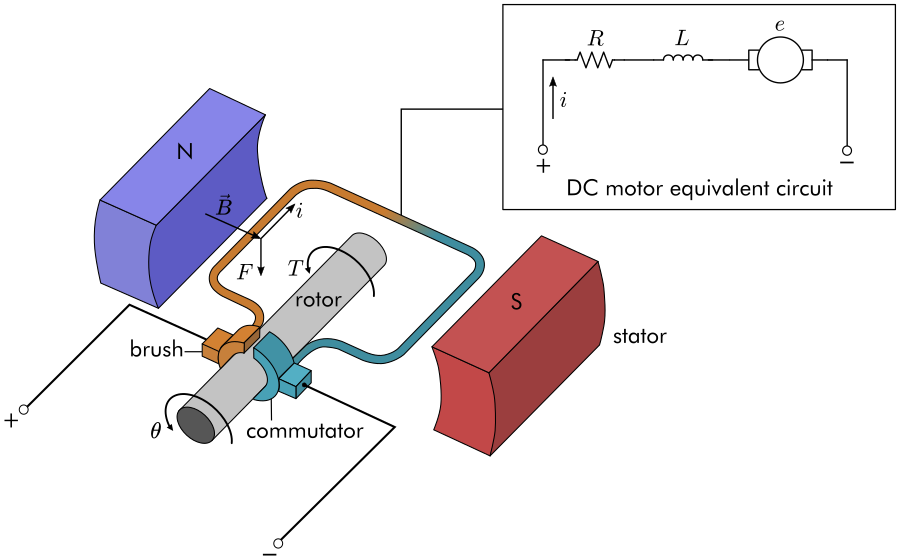


$$iR + L \frac{di}{dt} + k_e \dot{\theta} = v$$


 
$$J \ddot{\theta} + b \dot{\theta}  = k_m i$$
      

We will assume $K = k_e = k_m$

## State space representation

The differential equations from above can also be expressed in state-space form by choosing the motor position, motor speed and armature current as the state variables. Again the armature voltage is treated as the input and the rotational position is chosen as the output.

State vector: $\mathbf{x} = \left[ \begin{array}{c} 
\theta \\
\dot{\theta} \\
i

\end{array} \right]$


$$\dot{\mathbf{x}}  = \left[ \begin{array}{c} 
\dot{\theta} \\
\ddot{\theta} \\
\dot{i}
\end{array} \right]   =  \left[ \begin{array}{ccc}
0 & 1 & 0 \\
0 & -\frac{b}{J} &  \frac{K}{J} \\
0 & -\frac{K}{L} & -\frac{R}{L} 
\end{array} \right] \left[ \begin{array}{c} 
\theta \\
\dot{\theta} \\
i
\end{array} \right]

  +  \left[ \begin{array}{c} 
0 \\
0 \\
\frac{1}{L}  
\end{array} \right] v  \\ 

\dot{\mathbf{x}} = A\mathbf{x} + Bv   \mbox{     } (1)$$


## Design requirements

We will want to be able to position the motor very precisely, thus the steady-state error of the motor position should be zero when given a commanded position. We will also want the steady-state error due to a constant disturbance to be zero as well. The other performance requirement is that the motor reaches its final position very quickly without excessive overshoot. In this case, we want the system to have a settling time of 40 ms and an overshoot smaller than 16%.

If we simulate the reference input by a unit step input, then the motor position output should have:

- Settling time less than 40 milliseconds

- Overshoot less than 16%

- No steady-state error, even in the presence of a step disturbance input

## Motor parameters

Do not change these values. 

J = 0.01; %kg.m^2
b = 0.1; %N.m.s 
K = 0.01; %V/rad/s
R = 1; %Ohm
L = 0.5; %H


## Problem statement

Design a state feedback controller to achieve all the design requirements provided above. Your submission should have detailed explanation your methodology along with evidence showing that you have met the requirements. 

## State feedback controller

#### System analysis

%setting up the state space model 
A = [0,1,0; 0,-b/J, K/J; 0, -K/L -R/L]; 
B = [0;0; 1/L]; 
C = [1 0 0];
D = 0; 
dcMotorSS = ss(A,B,C,D); 

pole(dcMotorSS)

ans =          0
   -9.9975
   -2.0025


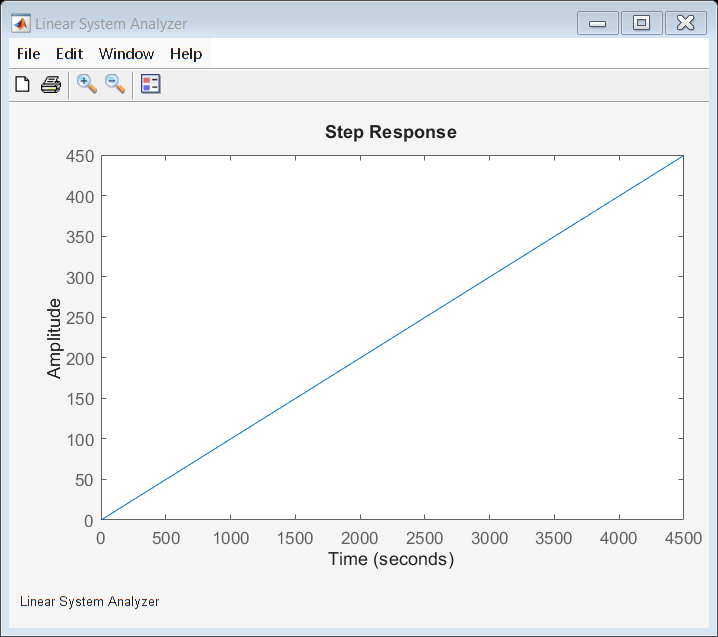

%Inspect characteristics of step response. 
linearSystemAnalyzer(dcMotorSS)

Note that the step response icreases continuously because of the pole at 0. Physically, this translates to the motor spinning at a constant rate, thus the angle keeps increasing at the rate of angular velocity. The controller's job will be to reduce the voltage input to the motor when the angle reaches the desired value. 

#### Pole placement

To obtaint the desired step response, we will place the poles at  -200, -200+100i, -200-100i. This pole placement locations were determine by "calculated guess" and trial-and-error. The observation here is the settling time decreases as the poles move towards the left, and as the imaginary component increases in magnitude.

p1 = -200;
p2 = -200 + 100i; 
p3 = conj(p2); 
Kc = place(A,B,[p1,p2,p3])

Kc = 1.0e+06 *

    5.0000    0.0620    0.0003


#### Analyse the system with feedback controller

The gain vector $K_c$ computed above can be used to implement the state feedback controller as shown in the figure below.

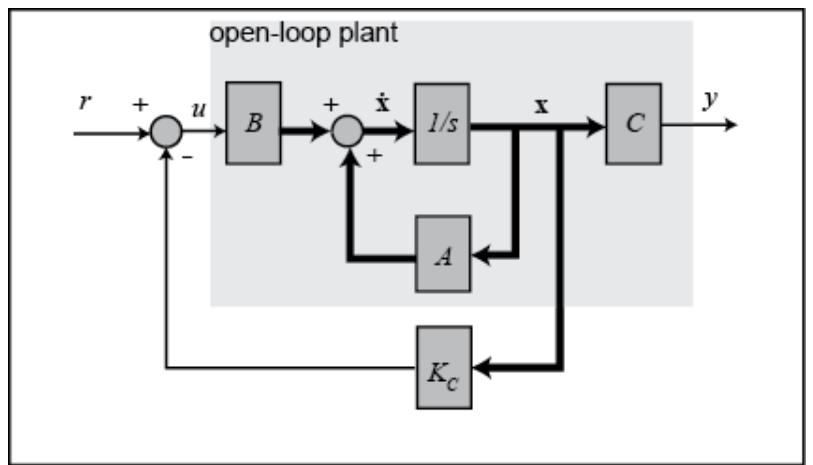

The state feedback controller updates the voltatage input accoring to the current state as follows 


$$\dot{\mathbf{x}} = A\mathbf{x} + B(v-K_c\mathbf{x})  = (A-BK_c)\mathbf{x} + Bv$$


where $v=r$ is the reference input. 

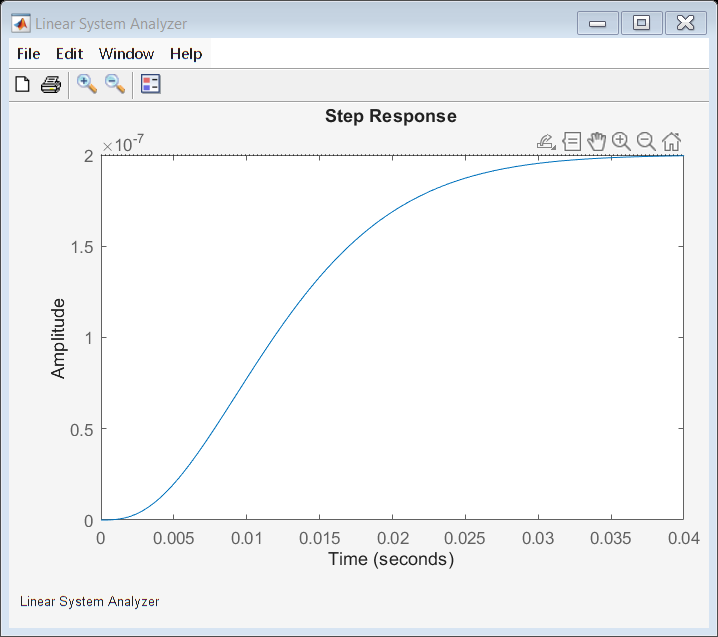

t = 0:0.01:3;
sys_cl = ss(A-B*Kc,B,C,D);

linearSystemAnalyzer(sys_cl)

Settling time: 30.6 seconds 

Overshoot: ~0 

#### Numerical computation of Steady-state output

[num,den] = ss2tf(A-B*Kc,B,C,D); 
syms s
num_sym = poly2sym(num, s);
den_sym = poly2sym(den, s);
transfer_function = num_sym / den_sym;
pretty(transfer_function)

                            2
--------------------------------------------------------
                       2
 3   2638827906662461 s    4466765987840293 s
s  + ------------------- + ------------------ + 10000000
        4398046511104          34359738368



steady_state_value = double(limit(transfer_function, s, 0))

steady_state_value = 2.0000e-07

Laplace transform of the output = transfer function * Laplace transform of the input 

Final value theroem 


$$\lim_{t\rightarrow \infty} {f(t)} = \lim_{s\rightarrow 0}{sF(s)}$$



$$F(s) = H(s).\frac{1}{s}$$


#### Adding a compensator for steady state error

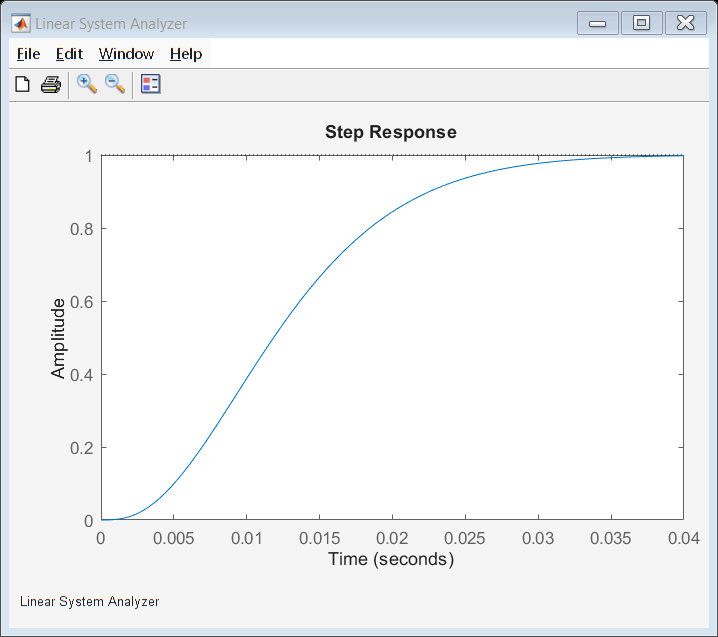

desiredSteadyState = 1; 
newSteadyState = steady_state_value; 
Nbar = desiredSteadyState/newSteadyState; 

linearSystemAnalyzer(Nbar*sys_cl);

## Adding a disturbance

The common source of disturbance for a motor is additional torque. With this additional torque, the second state equation is mofidief to: 

 
$$J \ddot{\theta} + b \dot{\theta}  = k_m i + T$$


This updates the state equation to the following: 


$$\dot{\mathbf{x}}  = \left[ \begin{array}{c} 
\dot{\theta} \\
\ddot{\theta} \\
\dot{i}
\end{array} \right]   =  \left[ \begin{array}{ccc}
0 & 1 & 0 \\
0 & -\frac{b}{J} &  \frac{K}{J} \\
0 & -\frac{K}{L} & -\frac{R}{L} 
\end{array} \right] \left[ \begin{array}{c} 
\theta \\
\dot{\theta} \\
i
\end{array} \right]

  +  \left[ \begin{array}{c} 
0 \\
0 \\
\frac{1}{L}  
\end{array} \right] v  
+ 
\left[ \begin{array}{c} 
0 \\
\frac{1}{J} \\
0 
\end{array} \right] T

\\  

\dot{\mathbf{x}} = A\mathbf{x} + Bv +  B_tT$$


Which along with the state feedback for voltage becomes 


$$\dot{\mathbf{x}} = A\mathbf{x} + B\left(v-K_c\mathbf{x}\right) +  B_tT \\
= \left(A - BK_c)\mathbf{x} + Bv + B_t T$$


Since this is a linear system, we can evaluate the effect of the disturbance torque $T$ by itself without the reference input ($$r=v=0$$) . In this case, if the system is starting from zero state, we want the system to come back to its zero state after the disturbance is applied.  The new system with just the input is 


$$\dot{\mathbf{x}} = \left(A - BK_c)\mathbf{x} + B_t T$$


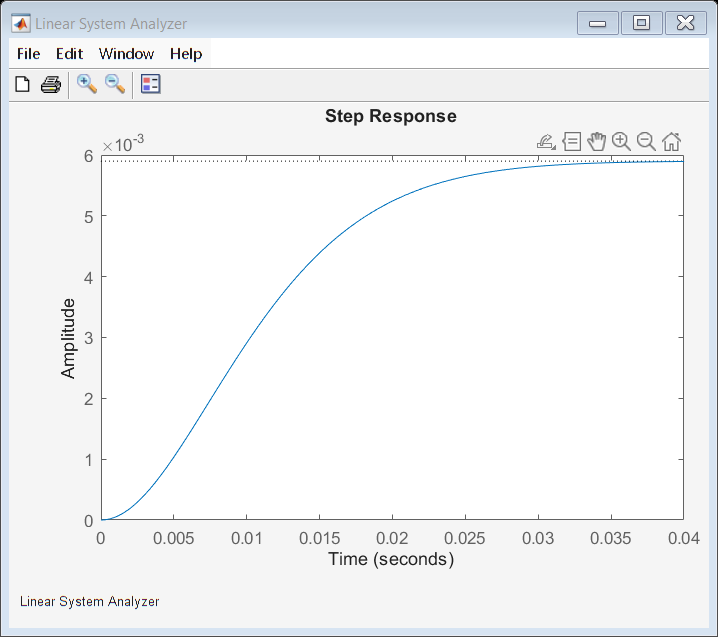

Bt = [0; 1/J ; 0]; 
dist_cl = ss(A-B*Kc,Bt, C, D);
linearSystemAnalyzer(dist_cl)

## Adding an integrator to compensate for the disturbance

Note that the steady state error is non-zero (the system doesn't return to zero state after the disturbance is applied). We have seen previously when learning about PID controllers, that an integrator can be used to remove the steady state error. Therefore, we will modify the control architecture as shown below: 

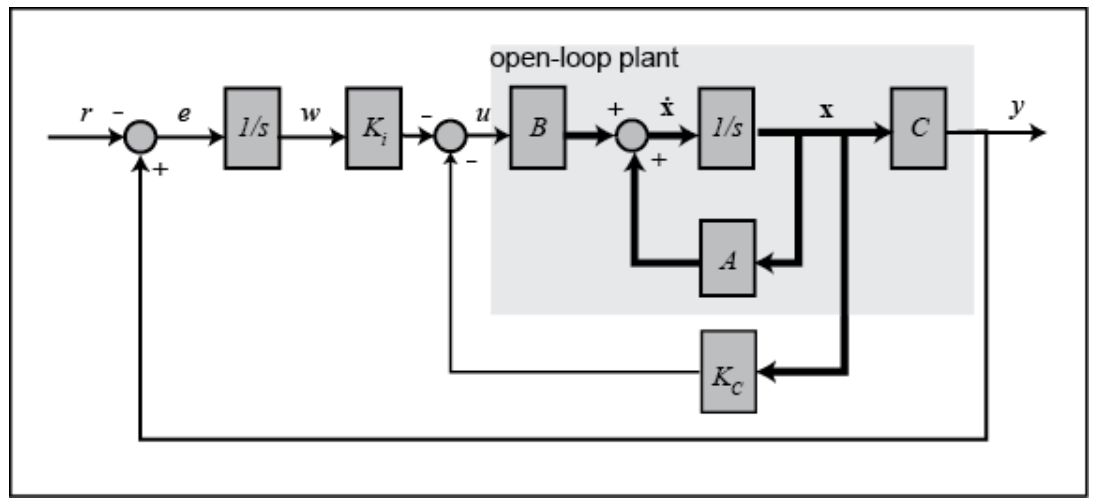

Using the above figure: 


$$u = -K_i w - K_c\mathbf{x}$$


and 


$$\dot{\mathbf{x}} = A\mathbf{x} + Bu \\
= A\mathbf{x} - BK_iw - BK_c \mathbf{x} \\
= (A-BK_c)\mathbf{x} - BK_i w \mbox{  } (2)$$


and 


$$\dot{w} = \theta - r\mbox{  } (3)$$


Combining equations (2) and (3) into a matrix equation, we get 


$$\left[ \begin{array}{c} 
\dot{\mathbf{x} \\
\dot{w}

\end{array} \right]  = 

\left[ \begin{array}{cc} 

A - BK_c & -BK_i \\
[1,0,0] & 0

\end{array} \right]

\left[ \begin{array}{c} 
\mathbf{x} \\
w 
\end{array} \right]

+ 

\left[ \begin{array}{c}
0\\0\\0\\-1
\end{array} \right] r  \\

\dot{\mathbf{x}}_a = A_a \mathbf{x}_a + B_ar
$$


Note that the addition of the integrator increased the dimension of the state vector by 1. We can write $A_a$ as follows: 


$$A_a = \left[ \begin{array}{cc} 

A - BK_c & -BK_i \\
[1,0,0] & 0

\end{array} \right] = 

\left[ \begin{array}{cc} 
A & 0 \\
[1,0,0] & 0
\end{array}\right]
+

\left[ \begin{array}{cc} 
-BK_c & -BK_i \\
0 & 0
\end{array}\right] \\
 
= A_1 - [B;0][K_c, K_i]  = A_1 - [B;0]K_a





$$


We can now use the place() function to ensure that the eigenvalues of $A_a$ (the poles of the system) are located to ensure stability of the system

a1 = [1,0,0]; 
A1 = [A,zeros(3,1); a1, 0]; 
p1 = -200; p2 = -200 + 100i; p3 = conj(p2);  p4 = -300; 
Ka = place(A1,[B;0],[p1,p2,p3,p4])

Ka = 1.0e+09 *

    0.0245    0.0002    0.0000    1.5000


### Simulating the system with the inegrator


$$
\dot{\mathbf{x}}_a = A_a \mathbf{x}_a + B_av
$$


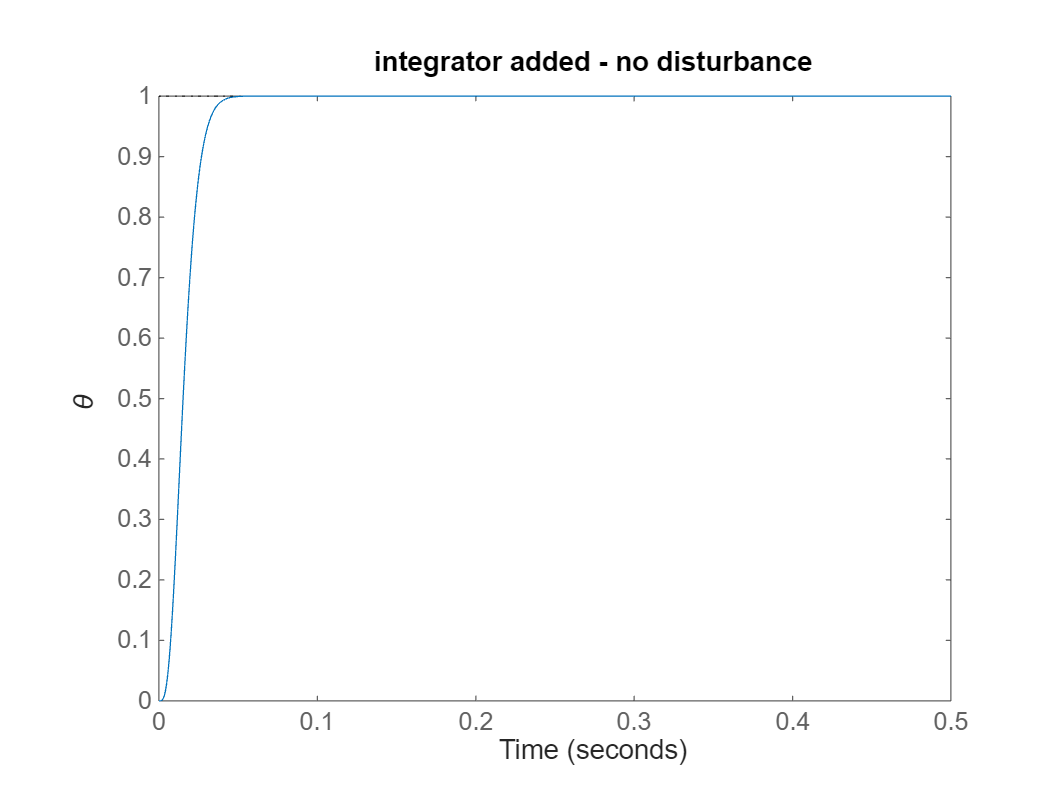

Aa = A1 - [B;0]*Ka; 
Ba = [0;0;0;-1];
withIntegrator = ss(Aa,Ba,[1,0,0,0],0); 
t = linspace(0,0.5,1000); 
step(withIntegrator,t)
ylabel('\theta')
title('integrator added - no disturbance')

Note that the new system does not have any steady state error. We can check if it sill meets the settling time requriements: 

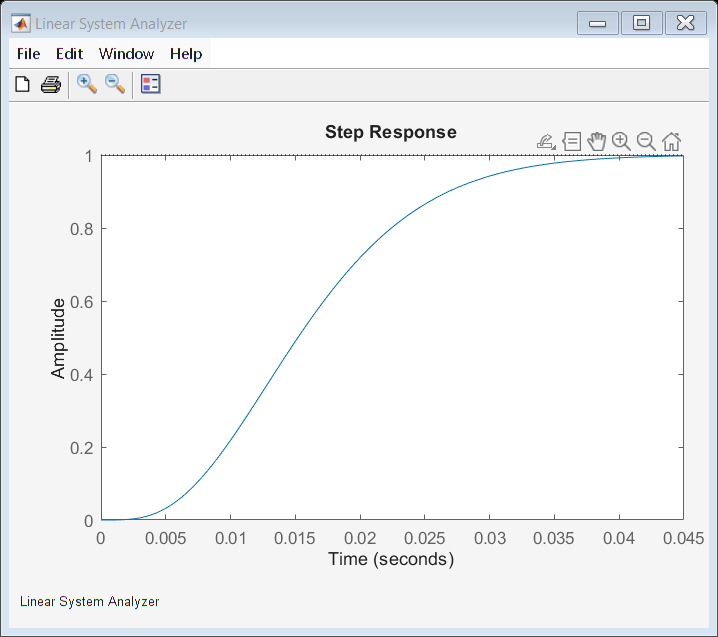

linearSystemAnalyzer(withIntegrator)

### Simulating with disturbance

The system with just the disturbance is 


$$\dot{\mathbf{x}}_a = A_a \mathbf{x}_a + B_tT$$


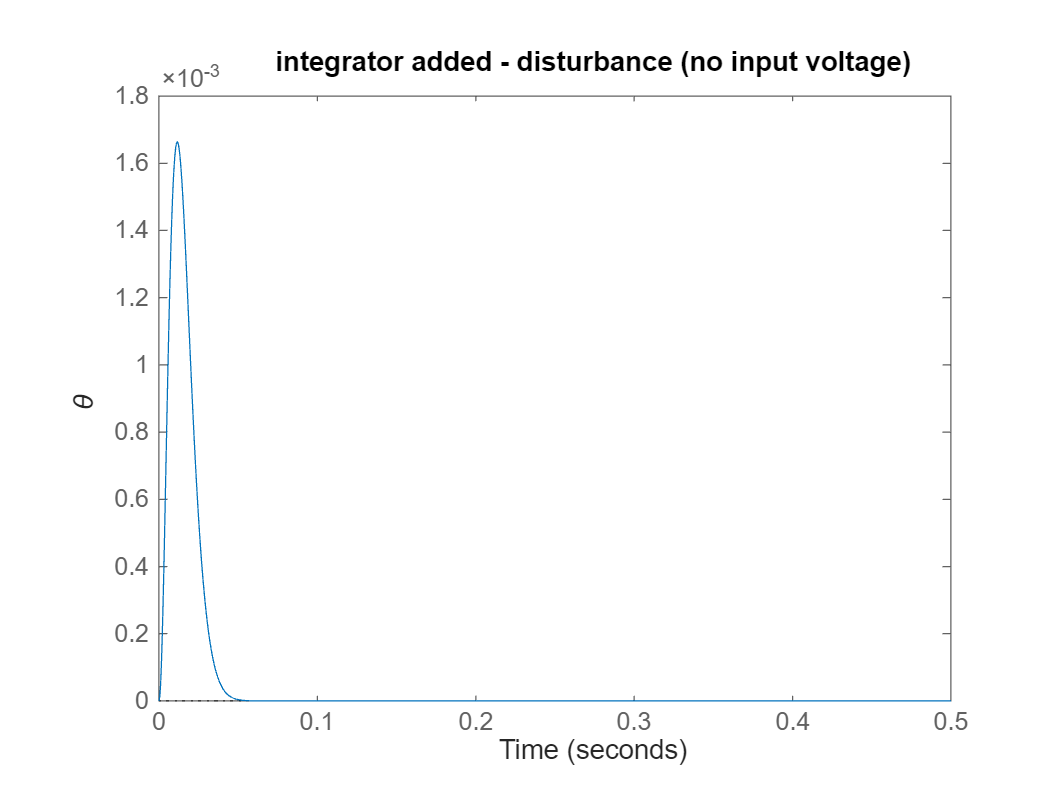

Bt = [0; 1/J ; 0]; 
withIntAndDist = ss(Aa,[Bt;0],[1,0,0,0], 0); 
t = linspace(0,0.5,1000); 
step(withIntAndDist,t)
ylabel('\theta')
title('integrator added - disturbance (no input voltage)')